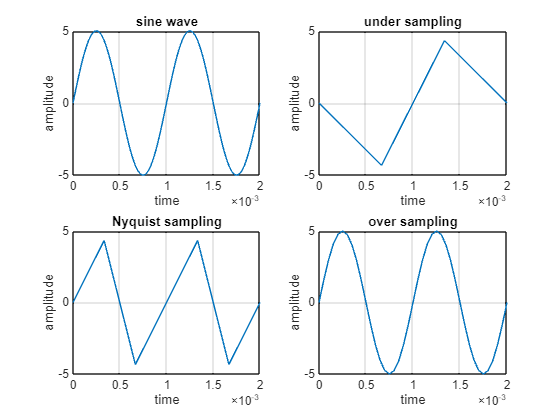

clc;
clf;
clear all;
close all;
Am = input('Enter Amplitude Am = ') ;
Fm = input('Enter the frequency of the signal Fm = ');
cy = input('Enter the number of Cycles required: ');
t = 0:1/(Fm*Fm):cy/Fm;
amplitude = Am*sin(2*pi*Fm*t);
subplot(221)
plot(t, amplitude) 
grid on; 
xlabel('time');
ylabel('amplitude');
title('sine wave');
fs1 = 1.5*Fm;
t1 = 0:1/fs1:cy/Fm;
amplitude1 = Am*sin(2*pi*Fm*t1);
subplot(222);
plot(t1, amplitude1);
grid on;
xlabel('time');
ylabel('amplitude');
title('under sampling');
fs2 = 3*Fm;
t2 = 0:1/fs2:cy/Fm;
amplitude2 = Am*sin(2*pi*Fm*t2);
subplot(223);
plot(t2, amplitude2);
grid on;
xlabel('time');
ylabel('amplitude');
title('Nyquist sampling');
fs3 = 20*Fm;  
t3 = 0:1/fs3:cy/Fm;
amplitude3 = Am*sin(2*pi*Fm*t3);
subplot(224);
plot(t3, amplitude3);
grid on;
xlabel('time');
ylabel('amplitude');
title('over sampling');